# Segmentación basada en la decompoisción Quadtree 

- Dada una región $R$ que representa toda la imagen, y dado un criterio de similitud $Q$

- Si $Q\left(R\right)=\textrm{False}$, se divide la imagen en cuadrantes.

- Si el criterio $Q$ no se cumple por un determinado cuadrante, se subdivide dicho cuadrante, y así de forma sucesiva.Esta técnica particular de división de la imagen tiene una representación conocida como **quadtree**. Es un árbol en el cual cada nodo tiene exactamente 4 descendientes.

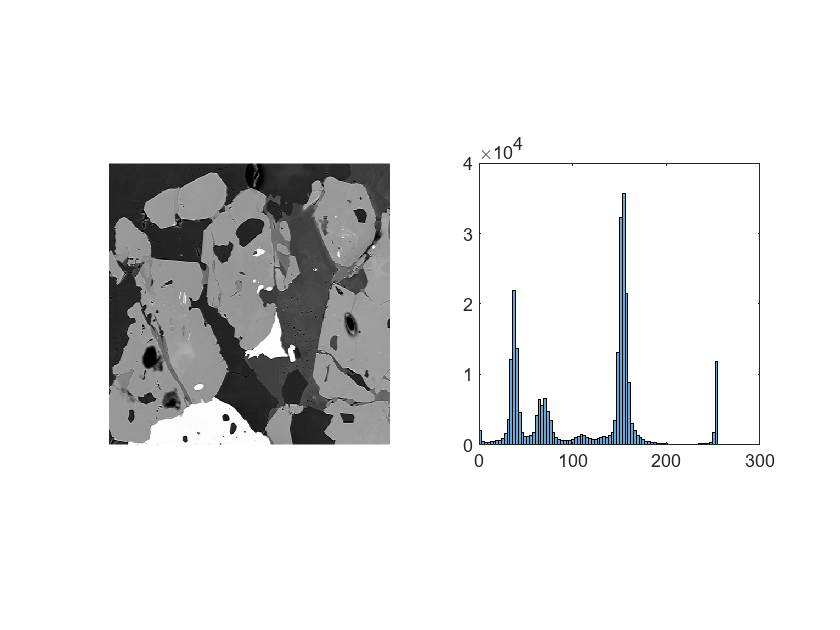

clc; close all; clear all

% read the input image
I= imread('.\sample images\BSE.jpg');
I=imresize(I,[512,512]);

% check the histogram to get the Otsu threshold
figure()
subplot(121);title('Original image')
imshow(I)
subplot(122)
h=histogram(I);axis square

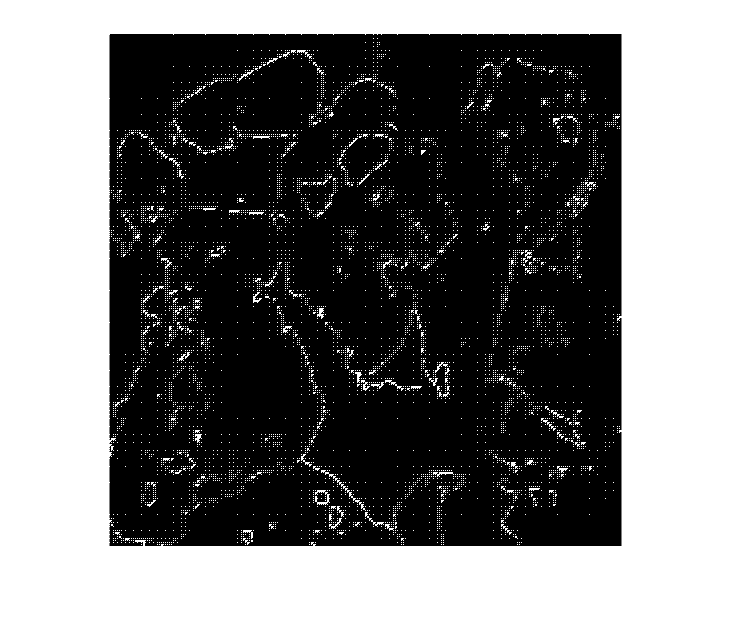

% compute the Otsu threshold
T = otsuthresh(h.Values);
%perform the quadtree decomposition
S = qtdecomp(I,T);
blocks = repmat(uint8(0),size(S));
Sfull=full(S);

figure()
imshow(Sfull)

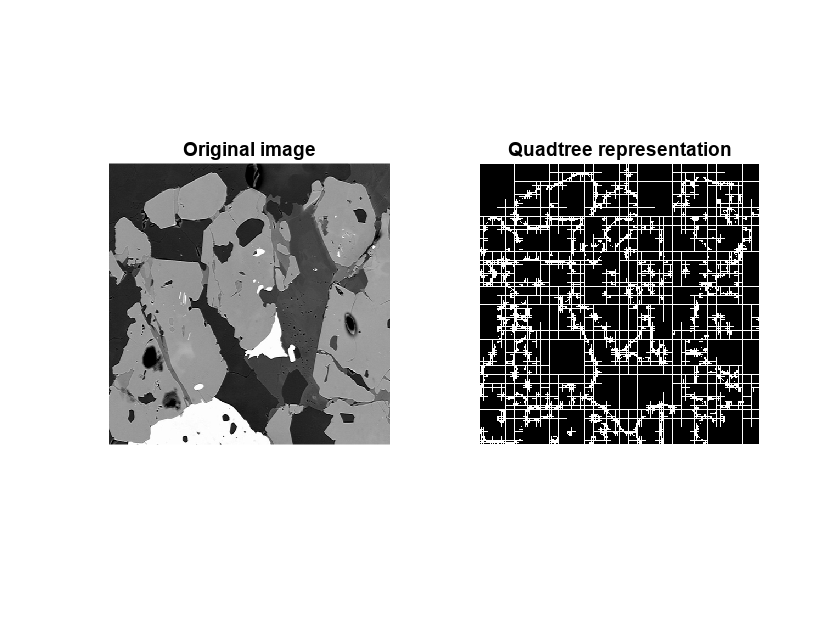

% Set block values in quadtree decomposition
% J = qtsetblk(I,S,dim,vals) replaces each dim-by-dim block in the quadtree decomposition 
% of image I with the corresponding block in vals. S contains the quadtree structure.

for dim = [512 256 128 64 32 16 8 4 2 1]   
  numblocks = length(find(S==dim));    
  if (numblocks > 0)        
    values = repmat(uint8(1),[dim dim numblocks]);
    values(2:dim,2:dim,:) = 0;
    blocks = qtsetblk(blocks,S,dim,values);
  end
end

blocks(end,1:end) = 1;
blocks(1:end,end) = 1;

figure()
subplot(121)
imshow(I)
title('Original image')
subplot(122)
imshow(blocks,[])
title('Quadtree representation')

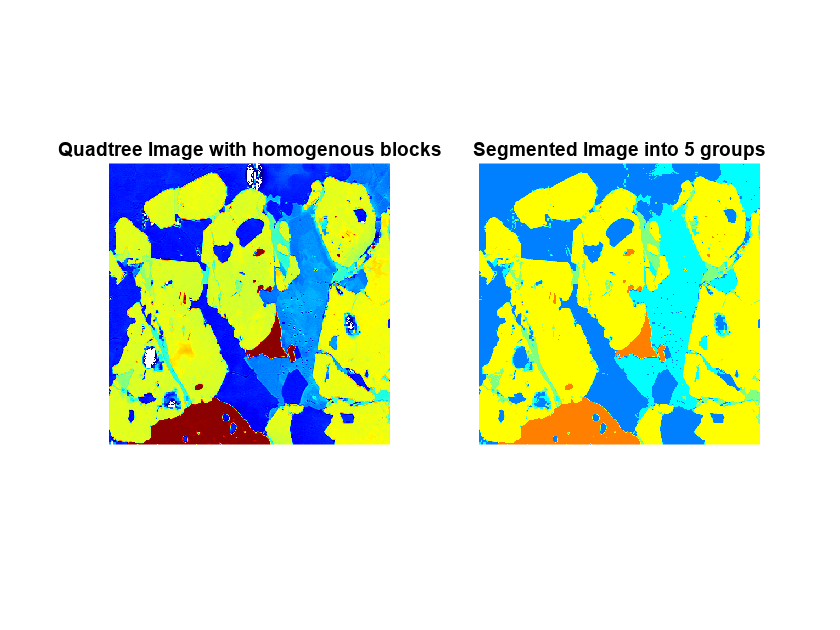

% Get the blocks of size 4-by-4 from the quadtree decomposition.
vals = qtgetblk(I,S,4);
% Calculate the mode of each 4-by-4 block, and set all values to equal the mode.
valmodes = zeros(size(vals));
for blknum = 1:size(vals,3)
    valmodes(:,:,blknum) = mode(vals(:,:,blknum),'all');
end
%Set the blocks in the image to the new values. The 4-by-4 blocks in the image are now homogenous.
J = qtsetblk(I,S,4,valmodes);
RGB1 = label2rgb(J);
% Now, we segment the quadtree decomposition using Otsu-thresholding
th = multithresh(J,4);
thr1 = imquantize(J,th);
RGB2 = label2rgb(thr1);
figure, 
subplot(121);imshow(RGB1); title('Quadtree Image with homogenous blocks')
subplot(122);imshow(RGB2), title('Segmented Image into 5 groups')